clc; clear all; close all; 

## Loading the data

varNames = ["x1-AFeed", "x2-DFeed", "x3-EFeed", "x4-TotalFeed", "x5-RecycleFlow", ...
    "x6-ReactorFeedRate", "x7-ReactorPressure", "x8-ReactorLevel", "x9-ReactorTemperature", ...
    "x10-PurgeRate", "x11-SeparatorTemperature", "x12-SeparatorLevel", ...
    "x13-SeparatorPressure", "x14-SeparatorUnderflow", "x15-StripperLevel", "x16-StripperPressure", ...
    "x17-StripperUnderflow", "x18-StripperTempreature",...
    "x19-StripperSteamFlow", "x20-CompressorWork", "x21-ReactorCoolOutT", "x22-SeparCoolOutT", ...
    "x23-ReactorCompA", "x24-ReactorCompB", "x25-ReactorCompC", "x26-ReactorCompD", "x27-ReactorCompE", ...
    "x28-ReactorCompF", "x29-PurgeCompA", "x30-PurgeCompB", "x31-PurgeCompC", "x32-PurgeCompD", ...
    "x33-PurgeCompE", "x34-PurgeCompF", "x35-PurgeCompG", "x36-PurgeCompH", ...
    "x37-ProdCompD", "x38-ProdCompE", "x39-ProdCompF", "x40-ProdCompG", "x41-ProdCompH", "x42-DFeedFlow", ...
    "x43-EFeedFlow", "x44-AFeedFlow", "x45-TotalFeedFlow", "x46-CompressorRecycleWave", "x47-PurgeValve", ...
    "x48-SeparatorProdLFlow", "x49-StripperProdLFlow", "x50-StripperSteamValve", "x51-ReactorCoolingWaterFlow", ...
    "x52-CondenserCoolingWaterFlow"];

X_healthy = load('d00_te.dat');
X_faulty  = load('d12_te.dat');

[nH, m] = size(X_healthy);
[nF, ~] = size(X_faulty);
fprintf('Healthy data: %d samples, %d variables\n', nH, m);

Healthy data: 960 samples, 52 variables


fprintf('Faulty data:  %d samples, %d variables\n', nF, m);

Faulty data:  960 samples, 52 variables


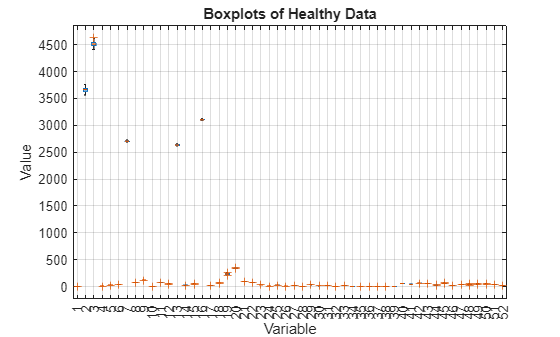


figure;
boxplot(X_healthy, 'Labels', 1:m);
xlabel('Variable');
ylabel('Value');
title('Boxplots of Healthy Data');
grid on;

## Scaling

Data is onn different physical scales, as observed in the boxplot. Let's standardize it.

mu  = mean(X_healthy);
sig = std(X_healthy);

Xh_scaled = (X_healthy - mu) ./ sig;
Xf_scaled = (X_faulty  - mu) ./ sig;



## PCA

We train a PCA model on the normal-operation data. Take a look and select an initial number of principal components. You will end up adjusting later on. 

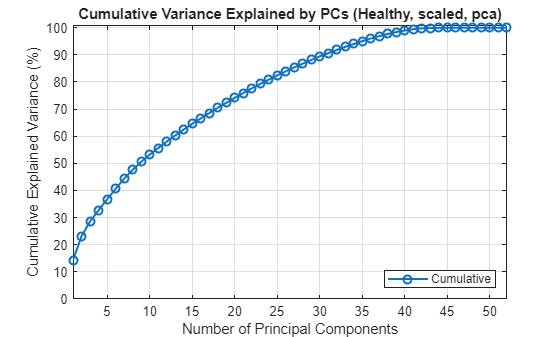

[coeff, score_h, latent, tsq_h, explained] = pca(Xh_scaled, ...
    'Centered', false, 'Algorithm', 'svd');

cumExpl = cumsum(explained);        

figure;
plot(1:m, cumExpl, 'o-', 'LineWidth', 1.5); hold on;
xlabel('Number of Principal Components');
ylabel('Cumulative Explained Variance (%)');
title('Cumulative Variance Explained by PCs (Healthy, scaled, pca)');
grid on; xlim([1, m]); ylim([0, 101]);
legend({'Cumulative'}, 'Location', 'southeast');
hold off;

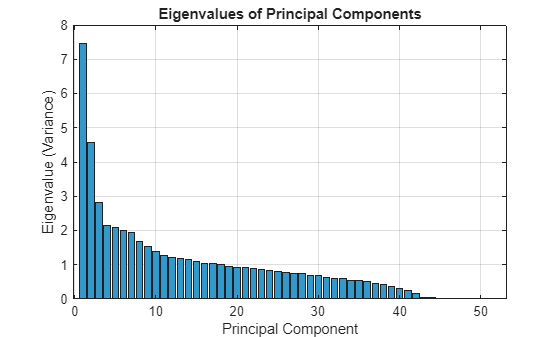


figure;
bar(latent, 'FaceColor',[0.2 0.6 0.8]);
xlabel('Principal Component');
ylabel('Eigenvalue (Variance)');
title('Eigenvalues of Principal Components');
grid on;

k = 3;   % <-- students: choose k (1..m)

[coeff_k, score_h_k, latent_k, tsq_h_k, explained_k] = pca( ...
    Xh_scaled, 'Centered', false, 'Algorithm', 'svd', 'NumComponents', k);


## Normal operating control charts

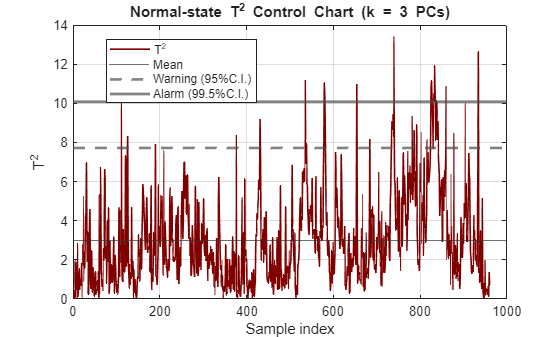

T2_h        = t2comp(Xh_scaled, coeff_k, latent_k, k);   
Q_h         = qcomp(Xh_scaled,  coeff_k, k);              

mu_T2       = mean(T2_h);  
sd_T2       = std(T2_h);
mu_Q        = mean(Q_h);   
sd_Q        = std(Q_h);

warn_T2     = mu_T2 + 2*sd_T2;   
alarm_T2    = mu_T2 + 3*sd_T2;
warn_Q      = mu_Q  + 2*sd_Q;    
alarm_Q     = mu_Q  + 3*sd_Q;

plotcol     = [0.5 0 0];   

figure;
plot(T2_h, '-', 'LineWidth',1.2, ...
    'Color', plotcol, 'MarkerFaceColor', plotcol);
hold on;
yline(mu_T2,'-','Color',[0.2 0.2 0.2]);
yline(warn_T2,'--','Color',[0.3 0.3 0.3],'LineWidth',2);
yline(alarm_T2,'-','Color',[0.3 0.3 0.3], 'LineWidth',2);
xlabel('Sample index'); ylabel('T^2');
title(sprintf('Normal-state T^2 Control Chart (k = %d PCs)', k));
legend({'T^2','Mean','Warning (95%C.I.)','Alarm (99.5%C.I.)'}, 'Location','best');
grid on; hold off;

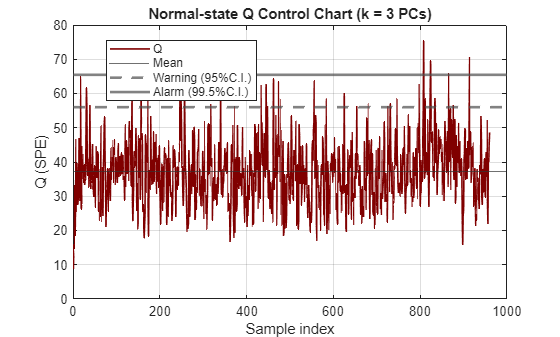


figure;
plot(Q_h, '-', 'LineWidth',1.2, ...
    'Color', plotcol, 'MarkerFaceColor', plotcol);
hold on;
yline(mu_Q,'-','Color',[0.2 0.2 0.2]);
yline(warn_Q,'--','Color',[0.3 0.3 0.3], 'LineWidth',2);
yline(alarm_Q,'-','Color',[0.3 0.3 0.3], 'LineWidth',2);
xlabel('Sample index'); ylabel('Q (SPE)');
title(sprintf('Normal-state Q Control Chart (k = %d PCs)', k));
legend({'Q','Mean','Warning (95%C.I.)','Alarm (99.5%C.I.)'}, 'Location','best');
grid on; hold off;

## Projecting on biplots

In which of these can you see the fault?

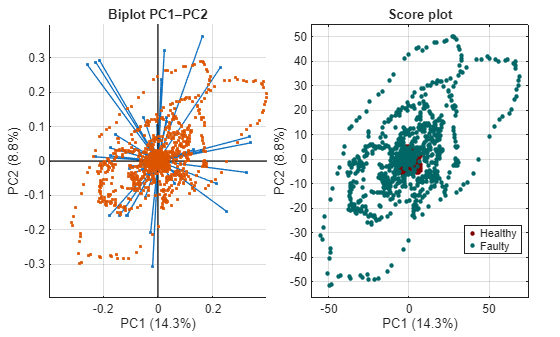

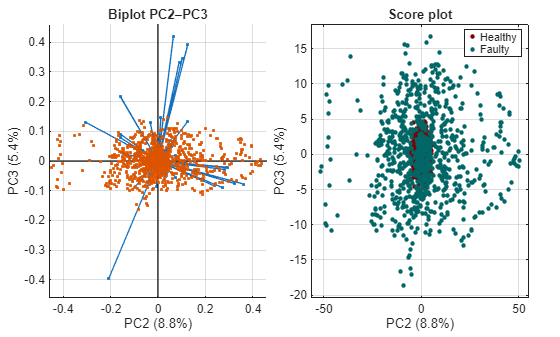

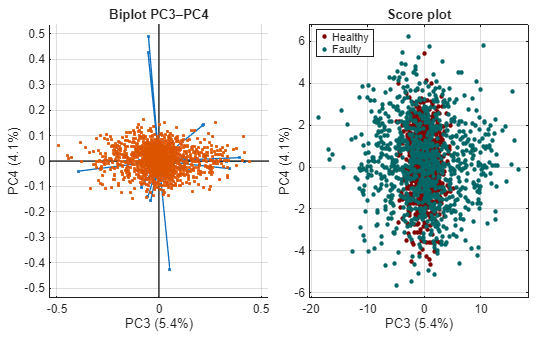

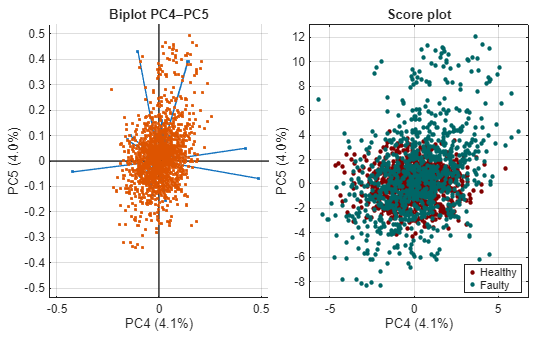

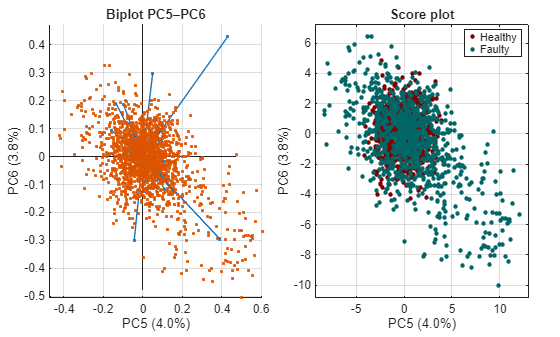

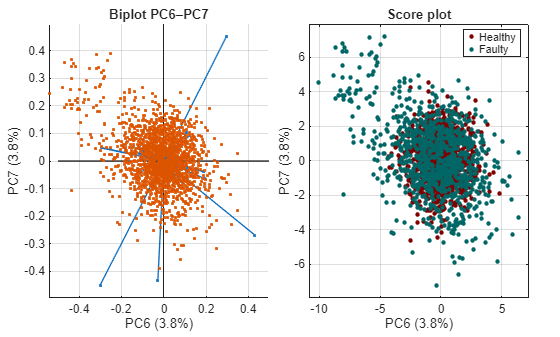

r = max(7, k);
[coeff_r, score_h_r, ~, ~, explained_r] = pca(Xh_scaled, ...
    'Centered', false, 'Algorithm', 'svd', 'NumComponents', r);
score_f_r = Xf_scaled * coeff_r;

burgundy = [0.50 0.00 0.00];
darkCyan = [0.00 0.40 0.40];
lw = 1.7; ms = 1.7;

nH = size(score_h_r,1);
nF = size(score_f_r,1);

for p = 1:6
    q = p + 1;

    SH = score_h_r(:,[p q]);
    SF = score_f_r(:,[p q]);
    scores_pair = [SH; SF];

    allScores = [SH; SF];
    xmin = min(allScores(:,1)); xmax = max(allScores(:,1));
    ymin = min(allScores(:,2)); ymax = max(allScores(:,2));
    mx = 0.05*max(1, xmax - xmin); my = 0.05*max(1, ymax - ymin);

    figure('Color','w');
    tiledlayout(1,2,'TileSpacing','compact','Padding','compact');

    nexttile;
    biplot(coeff_r(:,[p q]), 'Scores', scores_pair);
    title(sprintf('Biplot PC%d–PC%d', p, q));
    xlabel(sprintf('PC%d (%.1f%%)', p, explained_r(p)));
    ylabel(sprintf('PC%d (%.1f%%)', q, explained_r(q)));

    nexttile; hold on; box on; grid on;
    plot(SH(:,1), SH(:,2), 'o', 'MarkerFaceColor', burgundy, ...
        'MarkerEdgeColor', burgundy, 'LineWidth', lw, 'MarkerSize', ms);
    plot(SF(:,1), SF(:,2), 'o', 'MarkerFaceColor', darkCyan, ...
        'MarkerEdgeColor', darkCyan, 'LineWidth', lw, 'MarkerSize', ms);
    xlabel(sprintf('PC%d (%.1f%%)', p, explained_r(p)));
    ylabel(sprintf('PC%d (%.1f%%)', q, explained_r(q)));
    title('Score plot');
    legend({'Healthy','Faulty'}, 'Location','best');
    xlim([xmin-mx, xmax+mx]); ylim([ymin-my, ymax+my]);
    hold off;
end

## Mapping on control charts

Remember! We keep the limits from the normal-operation.

Also remember that the fault develops after 8 hours of operation.

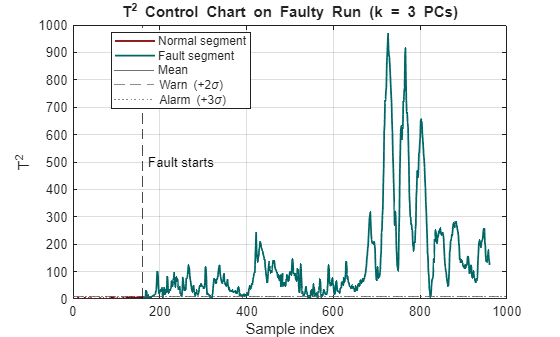

idxBreak = 160;                 % last index of the normal segment in the "faulty" run
nF = size(Xf_scaled,1);
burgundy = [0.50 0.00 0.00];    
darkCyan = [0.00 0.40 0.40];    
lw = 1.3;

T2_f = t2comp(Xf_scaled, coeff_k, latent_k, k);   
Q_f  = qcomp(Xf_scaled,  coeff_k, k);            

figure('Color','w'); hold on; box on; grid on;
plot(1:idxBreak, T2_f(1:idxBreak), '-', 'Color', burgundy, 'LineWidth', lw, 'Marker', 'none');
if idxBreak < nF
    plot(idxBreak+1:nF, T2_f(idxBreak+1:end), '-', 'Color', darkCyan, 'LineWidth', lw, 'Marker', 'none');
end

yline(mu_T2,   '-',  'Color',[0.2 0.2 0.2]);
yline(warn_T2, '--', 'Color',[0.35 0.35 0.35]);
yline(alarm_T2,':',  'Color',[0.35 0.35 0.35]);

xline(idxBreak+0.5, '--k', 'Fault starts', 'LabelOrientation','horizontal', 'LabelVerticalAlignment','middle');

xlabel('Sample index'); ylabel('T^2');
title(sprintf('T^2 Control Chart on Faulty Run (k = %d PCs)', k));
legend({'Normal segment','Fault segment','Mean','Warn (+2\sigma)','Alarm (+3\sigma)'}, 'Location','best');
hold off;

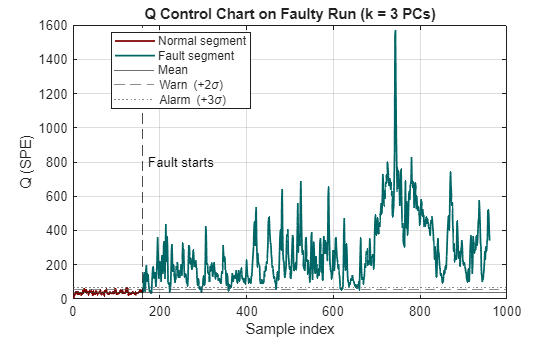


figure('Color','w'); hold on; box on; grid on;
plot(1:idxBreak, Q_f(1:idxBreak), '-', 'Color', burgundy, 'LineWidth', lw, 'Marker', 'none');
if idxBreak < nF
    plot(idxBreak+1:nF, Q_f(idxBreak+1:end), '-', 'Color', darkCyan, 'LineWidth', lw, 'Marker', 'none');
end

yline(mu_Q,   '-',  'Color',[0.2 0.2 0.2]);
yline(warn_Q, '--', 'Color',[0.35 0.35 0.35]);
yline(alarm_Q,':',  'Color',[0.35 0.35 0.35]);

xline(idxBreak+0.5, '--k', 'Fault starts', 'LabelOrientation','horizontal', 'LabelVerticalAlignment','middle');

xlabel('Sample index'); ylabel('Q (SPE)');
title(sprintf('Q Control Chart on Faulty Run (k = %d PCs)', k));
legend({'Normal segment','Fault segment','Mean','Warn (+2\sigma)','Alarm (+3\sigma)'}, 'Location','best');
hold off;

## Control chart creation

Choose the index of a variable you wish to visualize.

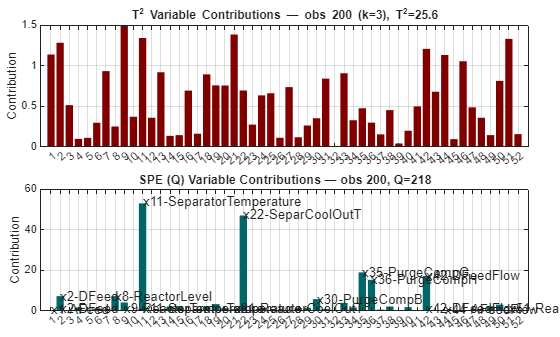

idxObs = 200;   % <-- students: choose in [161 .. size(Xf_scaled,1)]
nF = size(Xf_scaled,1);
assert(idxObs >= 161 && idxObs <= nF, 'Pick idxObs in [161, %d].', nF);

xrow = Xf_scaled(idxObs, :);   
T2_contrib = t2contr(xrow, coeff_k, latent_k, k);  
Q_contrib  = qcontr(xrow,  coeff_k, k);            
T2_val = t2comp(xrow, coeff_k, latent_k, k);
Q_val  = qcomp(xrow,  coeff_k, k);

burgundy = [0.50 0.00 0.00];
darkCyan = [0.00 0.40 0.40];

figure('Color','w');
tiledlayout(2,1,'TileSpacing','compact','Padding','compact');

nexttile;
bar(T2_contrib, 'FaceColor', burgundy, 'EdgeColor', 'none');
title(sprintf('T^2 Variable Contributions — obs %d (k=%d), T^2=%.3g', idxObs, k, T2_val));
ylabel('Contribution');
xticks(1:numel(varNames)); xticklabels(1:length(varNames)); xtickangle(40);
grid on; box on;

nexttile;
bar(Q_contrib, 'FaceColor', darkCyan, 'EdgeColor', 'none');
title(sprintf('SPE (Q) Variable Contributions — obs %d, Q=%.3g', idxObs, Q_val));
ylabel('Contribution');
xticks(1:numel(varNames)); xticklabels(1:length(varNames)); xtickangle(40);
grid on; box on;

[~,ixT] = maxk(T2_contrib, 8); text(ixT, T2_contrib(ixT)*1.02, varNames(ixT));
[~,ixQ] = maxk(Q_contrib,  8); text(ixQ, Q_contrib(ixQ)*1.02,  varNames(ixQ));

## Functions

function T2varcontr    = t2contr(data, loadings, latent, comp)
    score           = data * loadings(:,1:comp);
    standscores     = bsxfun(@times, score(:,1:comp), 1./sqrt(latent(1:comp,:))');
    T2contr         = abs(standscores*loadings(:,1:comp)');
    T2varcontr      = sum(T2contr,1);
end

function Qcontr   = qcontr(data, loadings, comp, aggregate)
    score         = data * loadings(:,1:comp);
    reconstructed = score * loadings(:,1:comp)';
    residuals     = bsxfun(@minus, data, reconstructed);

    contrib = residuals.^2;  

    if nargin < 4 || isempty(aggregate)
        Qcontr = contrib;                 
    elseif strcmpi(aggregate, 'per-variable')
        Qcontr = sum(contrib, 1);         
    elseif strcmpi(aggregate, 'per-observation')
        Qcontr = sum(contrib, 2);        
    else
        error('qcontr:BadArg', 'aggregate must be [], ''per-variable'', or ''per-observation''.');
    end
end

function Qfac   = qcomp(data, loadings, comp)
    score       = data * loadings(:,1:comp);
    reconstructed = score * loadings(:,1:comp)';
    residuals   = bsxfun(@minus, data, reconstructed);
    Qfac        = sum(residuals.^2,2);
end

function T2     = t2comp(data, loadings, latent, comp)
    score       = data * loadings(:,1:comp);
    standscores = bsxfun(@times, score(:,1:comp), 1./sqrt(latent(1:comp,:))');
    T2          = sum(standscores.^2,2);
end

function z = standardize(data, mu, sigma)
    sigma0 = sigma;
    sigma0(sigma==0) = 1;
    z = bsxfun(@minus, data, mu);
    z = bsxfun(@rdivide, z, sigma0);
end